# 3301 Major Project Optimisation

clearvars;

## Read in the data and do some preprocessing

dateFormat = "dd/MM/yyyy HH:mm";
analYear = 2021;

% It seems matlab already reads in .csv automatically with date-times, nice
nemData = readtable("20211008 OpenNEM.csv");


% There seems to be a "energy requirement" column in this that may be
% useful when calculating how much energy the battery loses
rawCarData = readtable("08G0VZET.csv");


% make the format consistent
nemData.date.Format = dateFormat;
rawCarData.datetime.Format = dateFormat;

% Make the datasets have the same year
nemData.date.Year = analYear;
rawCarData.datetime.Year = analYear;

% The NEM data is much smaller than the car data, so we extract the car
% data rows which allign with the NEM data
idx = ismember(rawCarData.datetime, nemData.date);
carData = rawCarData(idx, :);

% Sanity check, these should have the same size and starting dates
length(nemData.date) == length(carData.datetime)

ans = logical
   1


nemData.date(1) == carData.datetime(1)

ans = logical
   1



% Convert NEM data to $ per kWh
nemData.Price_AUD_kWh = nemData.Price_AUD_MWh * 1e-3;

## Define objective function

% This currently is just the prices for energy at each interval. There are
% negative values? Not sure what that means.
prices = nemData.Price_AUD_kWh;
availability = carData.available;

%Penalising Battery over/undercharging

% The car cannot earn money on the grid while it is out.
decVariables = prices.*availability 

decVariables =    -0.0664
   -0.0499
         0
         0
         0
         0
         0
         0
         0
         0


## Stop car from charging while it is out

unavailability = 1-availability;

Aeq = diag(unavailability);
% It still loses charge from the drive
beq = -carData.energyrequirement; % Discharge is negative

## Charge and discharge limits (sliders in kW)

% Charge limits are removed at the times the car is out
removeLimits = unavailability;
removeLimits(removeLimits==1) = inf;

% Convert kW to the actual amount which can be discharged in 5 mins
discharge = 7* (5/60);
lb = -discharge*ones(length(decVariables), 1) - removeLimits;

charge =7* (5/60);
ub =  charge*ones(length(decVariables), 1) + removeLimits;

## Capacity Limits

capacity = 40; % 40kW is the nissan leaf battery
soc = 0.8; % Car starts with some juice in it
A_1 = tril(ones(length(decVariables), length(decVariables))) ;
b_1 = (1-soc) * capacity * ones(length(decVariables), 1);

## Cant discharge battery below 0

A_2 = -1*tril(ones(length(decVariables), length(decVariables)));
b_2 = soc*capacity*ones(length(decVariables), 1);

## Any energy exported is wasted, dont export

% This isnt needed anymore
% A_3 = -1*eye(24);
% L = tbl.Load;
% S = tbl.Generation;
% b_3 = L-S;

## Add Battery Degradation Penalty to Objective Function

prices.*availability

ans =    -0.0664
   -0.0499
         0
         0
         0
         0
         0
         0
         0
         0


% Factor (higher = smaller penalisation)
penalisation_factor = 10

penalisation_factor = 1

% Linear penalty for battery charge (higher charge = higher penalty)
% perceived_price = (1 + battery_charge/(penalisation_factor*capacity))*actual_price
% Would prefer a quadratic penalty function but gets very complicated.
H = 1/(capacity*penalisation_factor) * tril(2.*prices.*availability.*ones(length(prices), length(prices)));
H = (H + H')/2

H =    -0.0033   -0.0012         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.0002   -0.0000   -0.0001    0.0001    0.0002    0.0004    0.0001
   -0.0012   -0.0025         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.0002   -0.0000   -0.0001    0.0001    0.0002    0.0004    0

f = (1 + soc/penalisation_factor).*prices.*availability;

## Add all the constraints to the same matrix

A = cat(1, A_1, A_2);
b = cat(1, b_1, b_2);

## Solve

[B, fval] = quadprog(H,f,A,b,Aeq,beq,lb,ub)


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


B =     0.5833
    0.5833
   -5.8350
         0
         0
         0
         0
         0
         0
         0


fval = -39.3145


[lin_B, lin_fval] = linprog(decVariables,A,b,Aeq,beq,lb,ub)

Optimal solution found.



lin_B =     0.5833
    0.5833
   -5.8350
         0
         0
         0
         0
         0
         0
         0


lin_fval = -25.2282


fval = B'*decVariables

fval = -24.3709


isequal(lin_B, B)

ans = logical
   0


## Plots

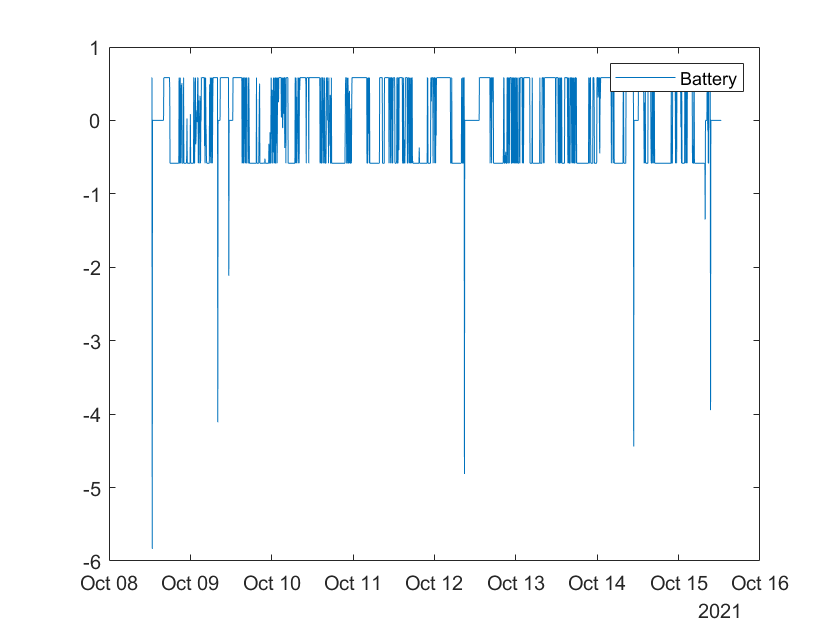

plot(nemData.date, B, 'DisplayName', 'Battery') % looks correct, the spikes are from when the car goes on a trip
legend

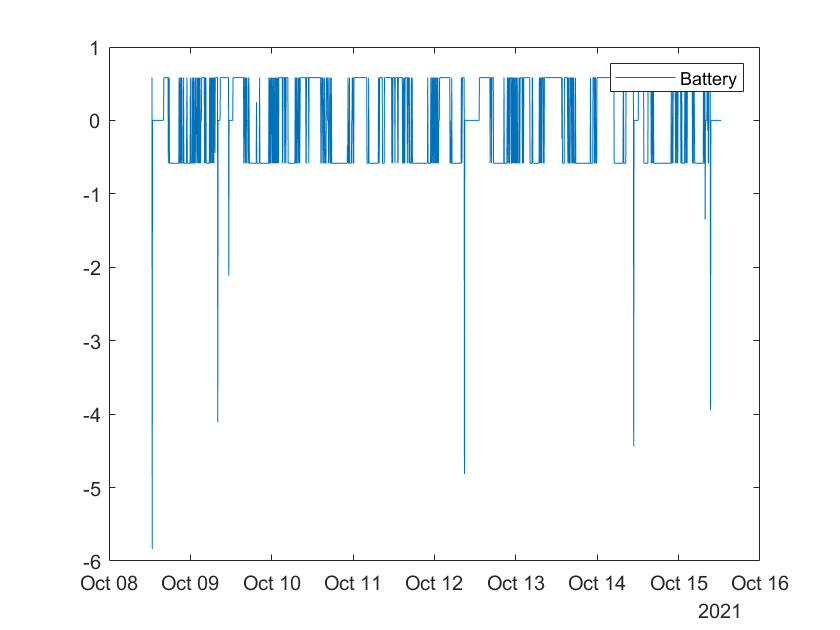

plot(nemData.date, lin_B, 'DisplayName', 'Battery') % looks correct, the spikes are from when the car goes on a trip
legend

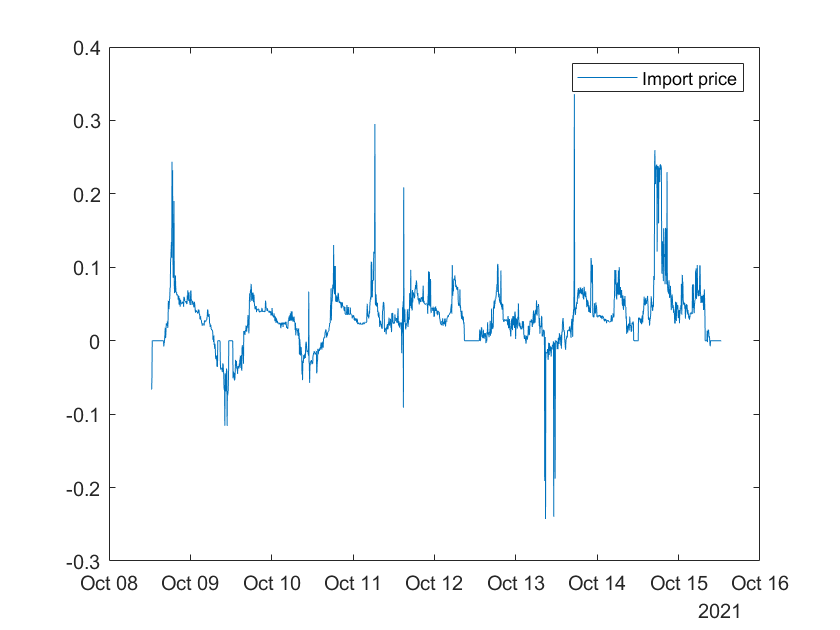

plot(nemData.date,decVariables,'DisplayName','Import price')
legend

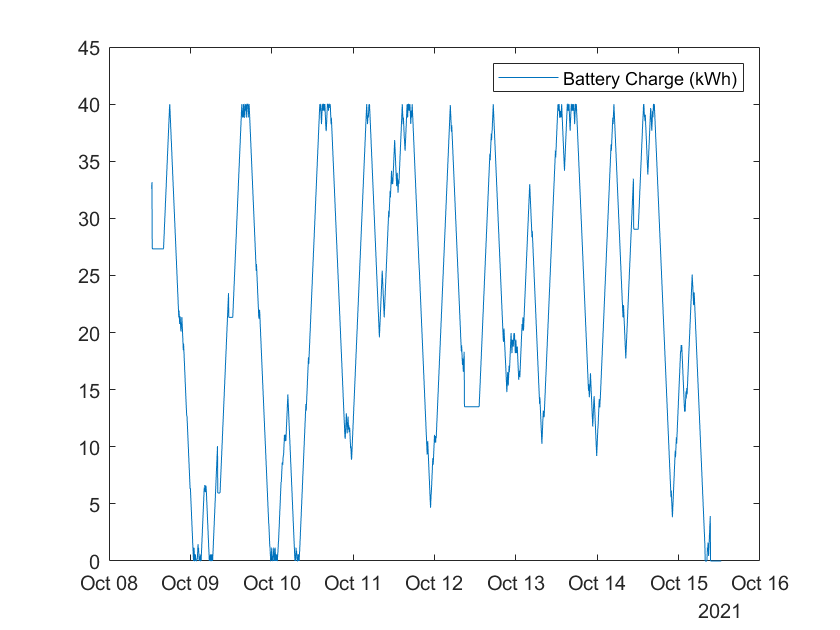

plot(nemData.date, cumsum(B) + soc*capacity,'DisplayName','Battery Charge (kWh)') % looks good, battery keeps within its capacity
legend

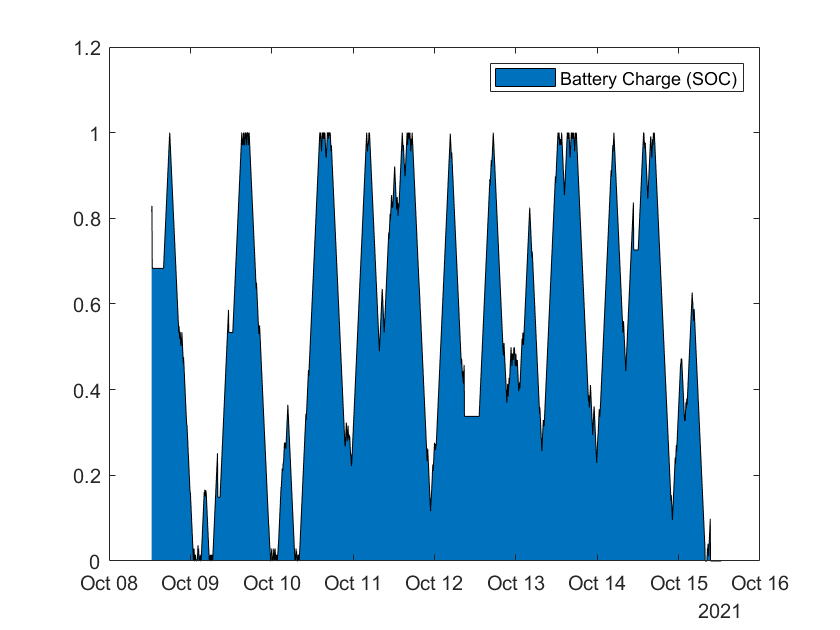

area(nemData.date, (cumsum(B) + soc*capacity)/capacity,'DisplayName','Battery Charge (SOC)') % looks good, battery keeps within its capacity
legend